# TP3 - Filtre de Kalman Étendu

# Estimation de l'état d'un moteur

Réalisé par Allory Besnard, Ronan Berdy et Hugo Bonnin.

## Introduction

Le présent bureau d'étude vise à développer et évaluer l'efficacité d'un filtre de Kalman étendu pour estimer l'état d'un moteur synchrone à aimants permanents. Le système est décrit par un ensemble d'équations différentielles décrivant le comportement électrique et mécanique du moteur.

## Description du Système

Le moteur synchrone à aimants permanents est modélisé par un ensemble d'équations différentielles représentant la partie électrique (dans le repère (α, β)) et la dynamique mécanique du rotor. Les équations sont formulées comme suit :


$$
\dot{i}_\alpha = -\frac{R}{L}i_\alpha + \frac{\omega \lambda}{L} \sin(\theta) +  \frac{u_\alpha + \Delta u_\alpha}{L} \\
\dot{i}_\beta = -\frac{R}{L}i_\beta +  \frac{\omega \lambda}{L} \sin(\theta) + \frac{u_\beta + \Delta u_\beta}{L} \\
\dot{\omega} = -\frac{3}{2J}\left(i_\alpha\sin(\theta) + i_\beta\cos(\theta)\right) - \frac{F\omega}{J} + \Delta\tau\\
\dot{\theta} = \omega
$$


Les courants $i_{\alpha \;}$ et $i_{\beta \;}$, la vitesse $\omega \;$, et l'angle $\theta \;$ constituent l'état du système. Les tensions $u_{\alpha \;}$ et $u_{\beta \;\;}$ sont les commandes d'entrée, soumises à des bruits $\Delta \;u_{\alpha \;}$ et $\Delta \;u_{\beta \;}$. Le bruit lié au couple de charge sur le rotor est représenté par $\Delta \;\tau \;$.

Nous commençons tout d'abord par poser la résistance R, l'inductance L, le flux électromagnétique $\lambda \;$, l'inertie mécanique J et le coefficient de frottement F.

R=2;
L=0.003;
lambda=0.1;
J=2e-3;
F=0.01; 

Nous posons également les paramètres de la distribution standard :

mu = 0;     % Moyenne
sigma_u_a = 0.001;  % Écart-type
sigma_u_b = 0.001;  % Écart-type
sigma_i_a = 0.1;  % Écart-type
sigma_i_b = 0.1;  % Écart-type
sigma_tau = 0.05;  % Écart-type

Nous générons les valeurs de x pour la plage souhaitée :

x = linspace(-0.001, 0.001, 1000);

Nous calculons ensuite la densité de probabilité pour chaque valeur de x :

y_u_a = normpdf(x, mu, sigma_u_a);
y_u_b = normpdf(x, mu, sigma_u_b);
y_i_a = normpdf(x, mu, sigma_i_a);
y_i_b = normpdf(x, mu, sigma_i_b);
y_tau = normpdf(x, mu, sigma_tau);

Nous initialisons ensuite les matrices de covariance ainsi que les variables d'état.

Pk=eye(4);
Pk_chapeau=eye(4);
t=0.001;
i_a=1;
i_b=1;
theta=1;
omega=1;
u_a=1;
u_b=1;

Le système étant non-linéaire, nous ne pouvons pas le mettre sous forme amtriciel. Nous avons donc effectué une approximation d'Euler pour obtenir un modèle discret du système.


$$x_{k+1} -x_k =t*\dot{x_k }$$


Nous définissons ensuite les matrices de prédiction G et C.

G=[t/L 0 0; 0 t/L 0; 0 0 t; 0 0 0];
C=[1 0 0 0;0 1 0 0];

Maintenant que tous les paramètres ont été initialisés, nous allons modéliser le comportement du système au fil du temps à l'aide d'une boucle.

xk_reel=[i_a ;i_b ;omega ;theta]; % Initialise le vecteur d'état réel du système
gamma=diag([sigma_u_a;sigma_u_b;sigma_tau]); % Initialise la matrice diagonale de covariance
k=1000; % Nombre d'itération de la simulation
xk_triangle=[0;0;0;0];
xk=[0;0;0;0];
for i=1:k
    %%% Systeme
    % Entrées de commande
    u_a = sin(0.1*i);
    u_b = cos(0.1*i);
    % Bruits générés par u_a, u_b, le rotor tau, et les courants i_a et i_b
    du_a = sqrt(0.001)*randn;
    du_b= sqrt(0.001)*randn;
    du_tau= sqrt(0.05)*randn;
    du_ia= sqrt(0.1)*randn;
    du_ib= sqrt(0.1)*randn;

    % Mise à jour de l'état réel du système 
    % xk_reel a été obtenu en intégrant le système par rapport à t
    xk_reel=[xk_reel(1)+t*(-(R/L)*xk_reel(1)+(xk_reel(3)*lambda/L)*sin(xk_reel(4))+(u_a+du_a)/L);...
        xk_reel(2)+t*(-(R/L)*xk_reel(2)+(xk_reel(3)*lambda/L)*sin(xk_reel(4))+(u_b+du_b)/L);...
        xk_reel(3)+t*(-3*xk_reel(1)*sin(xk_reel(4))/(2*J)+3*xk_reel(2)*cos(xk_reel(4))/(2*J)-F*xk_reel(3)/J+du_tau);...
        xk_reel(4)+t*xk_reel(3)];
    w=[du_ia;du_ib];
    W=eye(2);
    yk_reel=C*xk_reel+W*w;

    %%% Prédiction
    %A_k à été obtenu en calculant la dérivée partielle de xk_reel
    A=[1-(t*R/L) 0 t*lambda*sin(xk(4))/L xk(3)*lambda*cos(xk(4))*t/L; ...
    0 1-t*R/L t*lambda*sin(xk(4))/L xk(3)*lambda*cos(xk(4))*t/L;...
    -3*t*sin(xk(4))/(2*J) 3*t*cos(xk(4))/(2*J) (1-t*F/J) -3*t*xk(1)*cos(xk(4))/(2*J)+3*t*xk(2)*sin(xk(4))/(2*J);...
    0 0 t 1];

    xk_triangle=[xk(1)+t*(-(R/L)*xk(1)+(xk(3)*lambda/L)*sin(xk(4))+u_a/L);...
        xk(2)+t*(-(R/L)*xk(2)+(xk(3)*lambda/L)*sin(xk(4))+u_b/L);...
        xk(3)+t*(-3*xk(1)*sin(xk(4))/(2*J)+3*xk(2)*cos(xk(4))/(2*J)-F*xk(3)/J);...
        xk(4)+t*xk(3)];

    Pk_triangle=A*Pk_chapeau*A'+G*gamma*G';


    %%% Correction
    ome=diag([sigma_i_a;sigma_i_b]);
    Kp=Pk_triangle*C'/(C*Pk_triangle*C'+W*ome*W'); % On joue sur omega
    Pk_chapeau=(eye(4)-Kp*C)*Pk_triangle;
    xk=xk_triangle+Kp*(yk_reel-C*xk_triangle); % Correction de l'estimation


    %%% Sauvegarde des données
    %i_a
    data_i_abruit(i)=[1 0]*yk_reel;
    data_i_a(i)=[1 0 0 0]*xk_reel;
    data_i_acorr(i)=[1 0 0 0]*xk;
    %i_b
    data_i_bbruit(i)=[0 1]*yk_reel;
    data_i_b(i)=[0 1 0 0]*xk_reel;
    data_i_bcorr(i)=[0 1 0 0]*xk;
    %omega
    data_i_omega(i)=[0 0 1 0]*xk_reel;
    data_i_omegacorr(i)=[0 0 1 0]*xk;
    %theta
    data_i_theta(i)=[0 0 0 1]*xk_reel;
    data_i_thetacorr(i)=[0 0 0 1]*xk;

    
end

Nous affichons maintenant les signaux réels, bruités et corrigés pour les comparer.

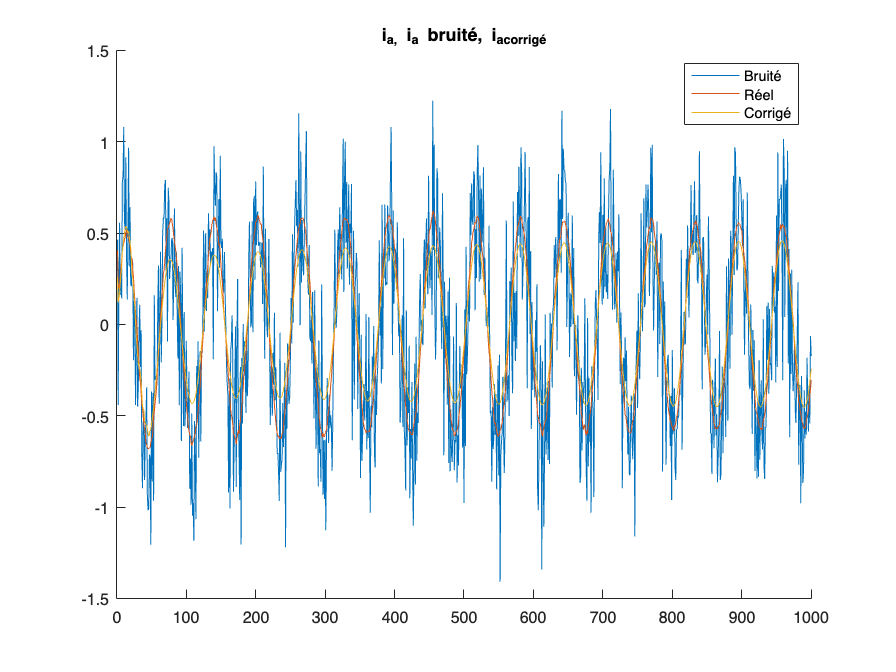

figure()
hold on
plot(data_i_abruit)
plot(data_i_a)
plot(data_i_acorr)
title('i_a, i_a bruité, i_a_corrigé')
legend('Bruité','Réel','Corrigé')
hold off

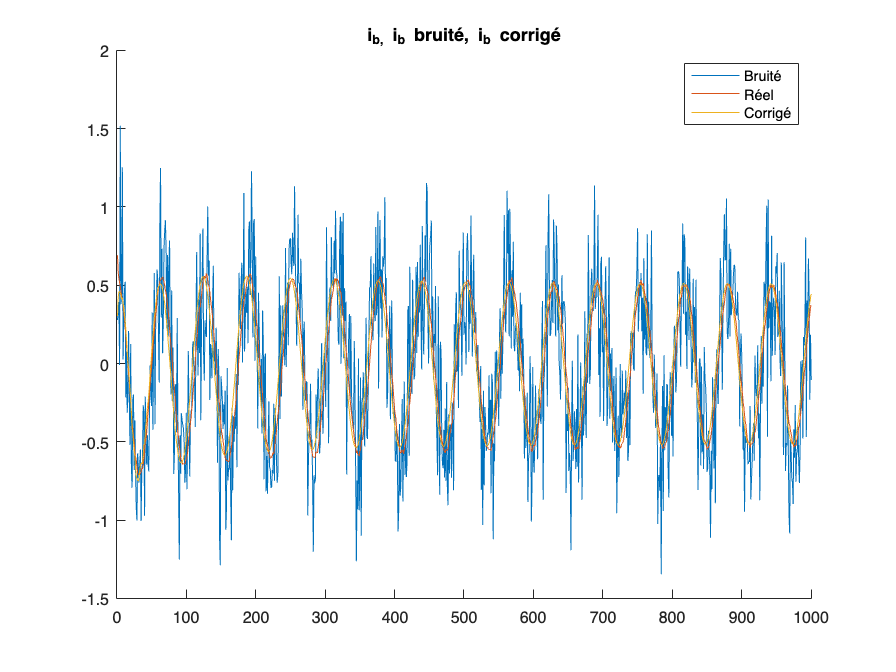

figure()
hold on
plot(data_i_bbruit)
plot(data_i_b)
plot(data_i_bcorr)
title('i_b, i_b bruité, i_b corrigé')
legend('Bruité','Réel','Corrigé')
hold off

L'application du filtre de Kalman aux signaux $i_{\alpha \;}$ et $i_{\beta \;}$démontre son efficacité dans la correction des données bruitées. Les courbes obtenues pour ces deux composantes illustrent clairement la capacité du filtre à estimer de manière précise l'état du système. En comparant les signaux corrigés aux signaux bruités et réels, il est évident que le filtre de Kalman parvient à atténuer le bruit tout en conservant une trajectoire cohérente avec le comportement réel du moteur. Cette observation suggère que le filtre de Kalman, tel que configuré dans notre simulation, est fonctionnel et offre une estimation robuste de l'état du moteur, même en présence de perturbations. Ces résultats renforcent la pertinence de l'approche utilisée pour estimer l'état du système et mettent en évidence les avantages du filtre de Kalman dans la réduction des effets indésirables du bruit dans les mesures.

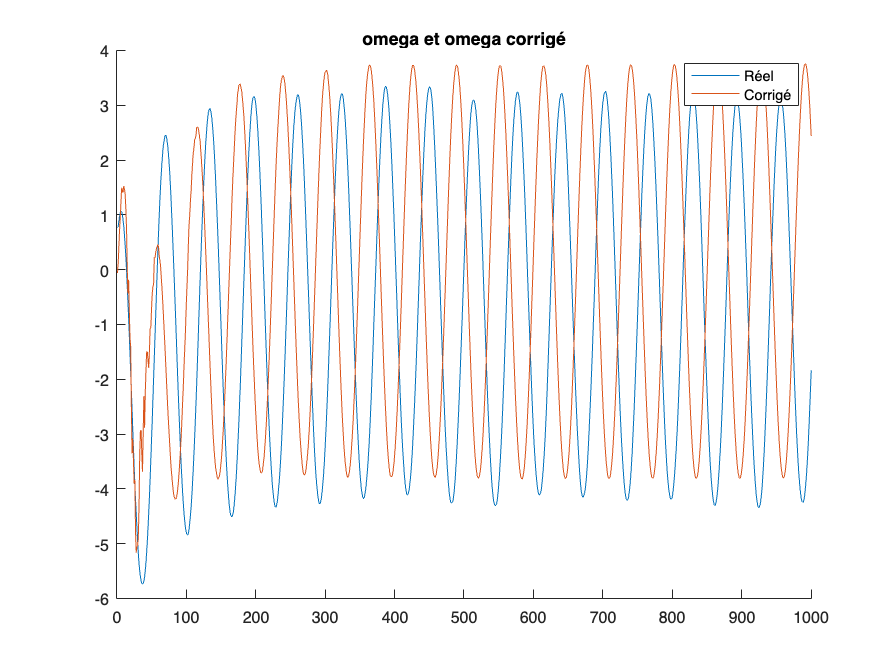

figure()
hold on
plot(data_i_omega)
plot(data_i_omegacorr)
title('omega et omega corrigé')
legend('Réel','Corrigé')
hold off

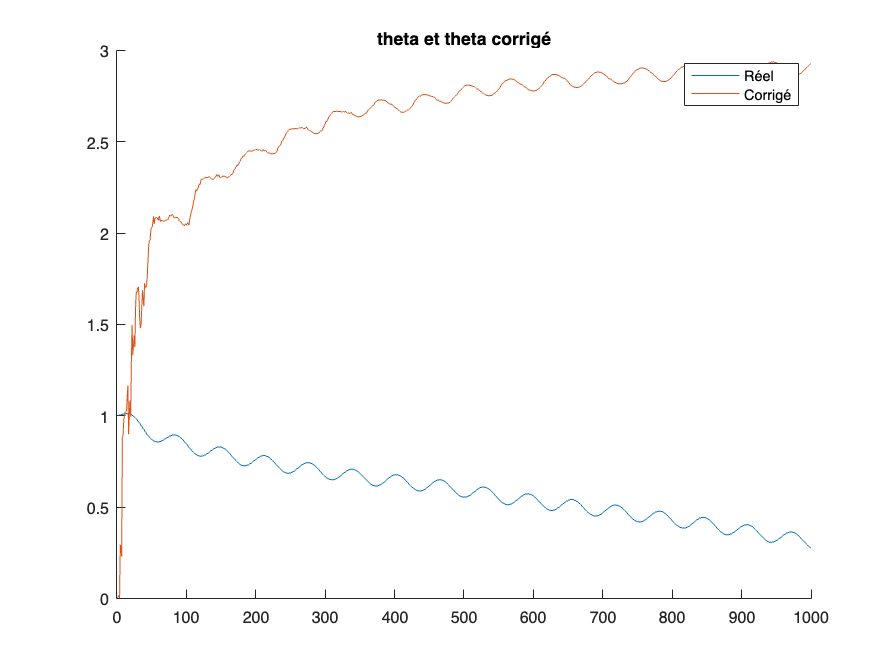

figure()
hold on
plot(data_i_theta)
plot(data_i_thetacorr)
title('theta et theta corrigé')
legend('Réel','Corrigé')
hold off